addpath(genpath('..'));


[name, dir] = uigetfile;
data1 =  load(strcat(dir,name));

[name, dir] = uigetfile;
data2 =  load(strcat(dir,name));

[name, dir] = uigetfile;
data2 =  load(strcat(dir,name));

data_points1 = data1.data_points;
data_points2 = data2.data_points;
data_points2 = data2.data_points;

Filter non tissue points

tissue1 = data_point.empty;
for i=1:length(data_points1)
    dp = copy(data_points1(i));
    dp.tissue_flag = 0;
    data_points1(i).tissue_flag = 0;
    if max(dp.intensity_data) > 20000
        data_points1(i).tissue_flag = 1;
        dp.tissue_flag = 1;
        tissue1 = [tissue1 dp];
    end
end

tissue2 = data_point.empty;
for i=1:length(data_points2)
    dp = copy(data_points2(i));
    data_points2(i).tissue_flag = 0;
    dp.tissue_flag = 0;
    if max(dp.intensity_data) > 20000
        dp.tissue_flag = 1;
        data_points2(i).tissue_flag = 1;
        tissue2 = [tissue2 dp];
    end
end

theta = 90*pi/180;
T = [cos(theta) sin(theta) 0;
    -sin(theta) cos(theta) 0;
    0 0 1];

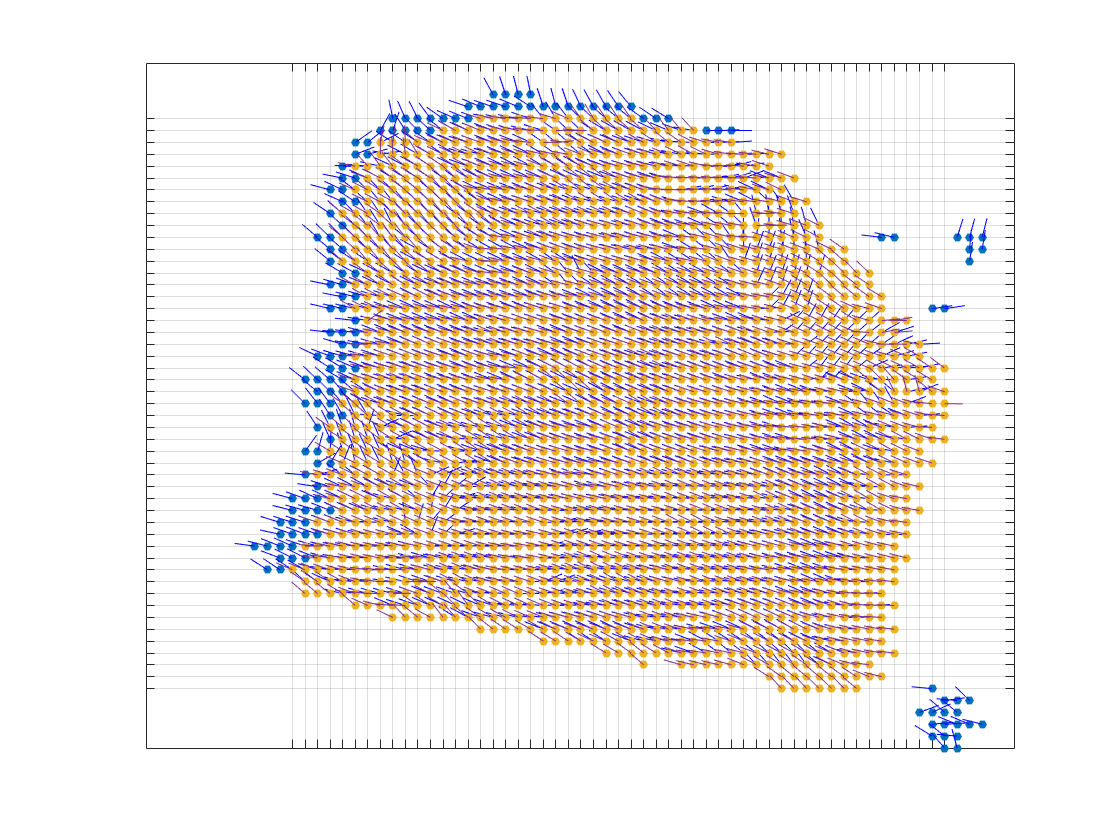

figure
hold on
scatter3([tissue1(:).x],[tissue1(:).y], zeros(1,length(tissue1)),20,'filled')
u1=cos([tissue1(:).mean_odf]);
v1=sin([tissue1(:).mean_odf]);
quiver3([tissue1(:).x],[tissue1(:).y], zeros(1,length(tissue1)), u1,v1,zeros(1,length(tissue1)),'b.','filled')

scatter3([tissue2(:).x],[tissue2(:).y], ones(1,length(tissue2)),20,'filled')
u2=cos([tissue2(:).mean_odf]);
v2=sin([tissue2(:).mean_odf]);
quiver3([tissue2(:).x],[tissue2(:).y], ones(1,length(tissue2)), u2,v2,zeros(1,length(tissue2)),'.','filled')

ax = gca;
ax.XTick = unique([tissue2(:).x]);
ax.YTick = unique([tissue2(:).y]);
set(gca,...
'XTickLabel','','YTickLabel','');

grid on
box on
hold off

all_data = {data_points1, data_points2};
all_tformed_data = {data_point.empty, data_point.empty};

[Ts, imageSize] = loadMatrices();

Ts_modified = Ts;
h = waitbar(0,'Applying Transformation');
for t=1:length(Ts)
    
    tformed_data = data_point.empty;
    sectionData = all_data{t};
    Ts_modified{t} = translateMatrices(all_data{t}, Ts{t}, imageSize(1,:));
    for i = 1:length(sectionData)
        h = waitbar(i/length(sectionData),h,sprintf('Applying Transformation to section %d',t));
        tformed_data(i) = sectionData(i).ApplyTransformation(Ts_modified{t});
    end
    all_tformed_data{t} = tformed_data; 
end
close(h);

tissue1_tformed = all_tformed_data{1};
tissue2_tformed = all_tformed_data{2};

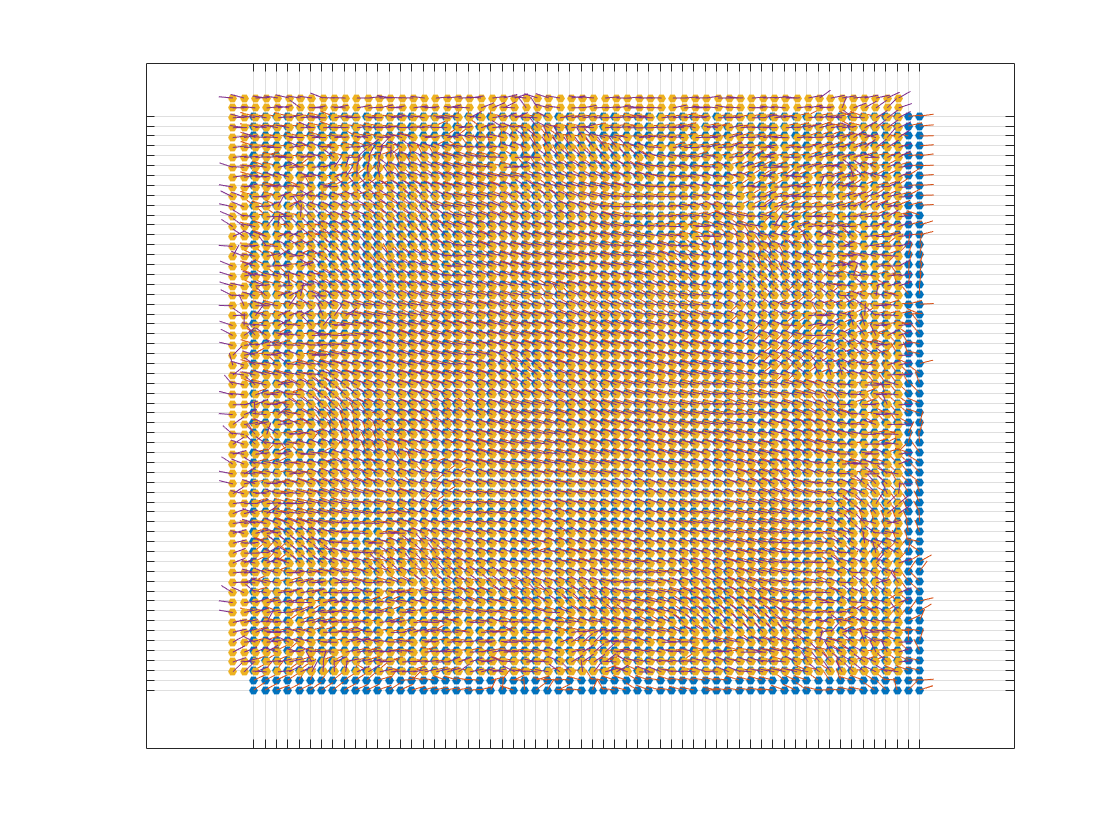

figure
hold on
scatter3([tissue1_tformed(:).x],[tissue1_tformed(:).y], zeros(1,length(tissue1_tformed)),20,'filled')
u1=cos([tissue1_tformed(:).mean_odf]);
v1=sin([tissue1_tformed(:).mean_odf]);
quiver3([tissue1_tformed(:).x],[tissue1_tformed(:).y], zeros(1,length(tissue1_tformed)), u1,v1,zeros(1,length(tissue1_tformed)),'.')

scatter3([tissue2_tformed(:).x],[tissue2_tformed(:).y], ones(1,length(tissue2_tformed)),20,'filled')
u2=cos([tissue2_tformed(:).mean_odf]);
v2=sin([tissue2_tformed(:).mean_odf]);
quiver3([tissue2_tformed(:).x],[tissue2_tformed(:).y], ones(1,length(tissue2_tformed)), u2,v2,zeros(1,length(tissue2_tformed)),'.')


ax = gca;
ax.XTick = unique([tissue1_tformed(:).x]);
ax.YTick = unique([tissue1_tformed(:).y]);
set(gca,...
'XTickLabel','','YTickLabel','');

grid on
box on
hold off

interpolated1 = interpolateScattered(tissue1_tformed, tissue2_tformed);

tissue1_interp = data_point.empty;
for i=1:length(interpolated1)
    dp = copy(interpolated1(i));
    if dp.tissue_flag >= 0.5
        tissue1_interp = [tissue1_interp dp];
    end
end
% tissue3_interp = data_point.empty;
% for i=1:length(interpolated3)
%     dp = copy(interpolated3(i));
%     if dp.tissue_flag >= 0.5
%         tissue3_interp = [tissue3_interp dp];
%     end
% end
tissue2_interp = data_point.empty;
for i=1:length(tissue2_tformed)
    if tissue2_tformed(i).tissue_flag >= 0.5
        tissue2_interp = [tissue2_interp tissue2_tformed(i)];
    end
end

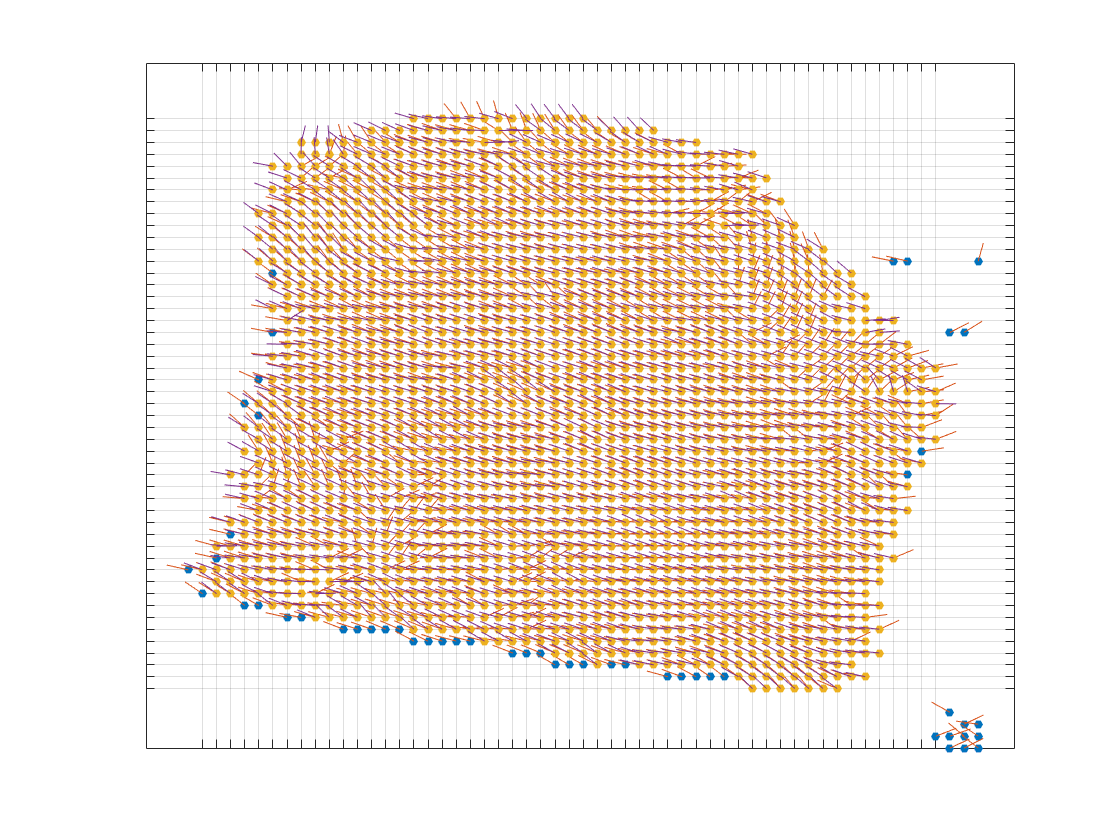

figure
hold on
scatter3([tissue1_interp(:).x],[tissue1_interp(:).y], zeros(1,length(tissue1_interp)),20,'filled')
u1=cos([tissue1_interp(:).mean_odf]);
v1=sin([tissue1_interp(:).mean_odf]);
quiver3([tissue1_interp(:).x],[tissue1_interp(:).y], zeros(1,length(tissue1_interp)), u1,v1,zeros(1,length(tissue1_interp)),'.')

scatter3([tissue2_interp(:).x],[tissue2_interp(:).y], ones(1,length(tissue2_interp)),20,'filled')
u2=cos([tissue2_interp(:).mean_odf]);
v2=sin([tissue2_interp(:).mean_odf]);
quiver3([tissue2_interp(:).x],[tissue2_interp(:).y], ones(1,length(tissue2_interp)), u2,v2,zeros(1,length(tissue2_interp)),'.')

% scatter3([tissue3_interp(:).x],[tissue3_interp(:).y], ones(1,length(tissue3_interp))*2,20,'filled')
% u2=cos([tissue3_interp(:).mean_odf]);
% v2=sin([tissue3_interp(:).mean_odf]);
% quiver3([tissue3_interp(:).x],[tissue3_interp(:).y], ones(1,length(tissue3_interp))*2, u2,v2,zeros(1,length(tissue3_interp)),'.')

ax = gca;
ax.XTick = unique([tissue2_interp(:).x]);
ax.YTick = unique([tissue2_interp(:).y]);
set(gca,...
'XTickLabel','','YTickLabel','');

grid on
box on
hold off

for i =1:length(tissue1_interp) tissue1_interp(i).z = 0; end
for i =1:length(tissue2_interp) tissue2_interp(i).z = 1; end

printToTextFile(tissue1_interp,',');
printToTextFile(tissue2_interp,',');


printToTecPlot([tissue1_interp, tissue2_interp], ',');